# Strategy IV command file

Source output rate

load('failure_rate.mat','failure_rate');
MTBF = 1./failure_rate; % 5=N of components % From Schedule statistics
MTBF_h = MTBF.*8544/WT_n; % MTBF, T in hours

## SINGLE USE CODE

soi = 1;
yoi = 1;
%
i = yoi;
j = soi;
% Load data
load('Failure_data_index.mat');
load('Failure_events_index.mat');
load('Schedule_data_index.mat');
clear Failure_events
clear Failure_data
clear Schedule_data
Failure_data = Failure_data_index(yoi,soi);
Failure_events = Failure_events_index(yoi,soi);
Schedule_data = Schedule_data_index(yoi,soi);
% Open model
open('Supply_Chain_II.slx');

## Data generator

if true
    load('Failure_data_index.mat');
    load('Failure_events_index.mat');
    load('Schedule_data_index.mat');
    for j = 1:3 % Series !!!
        soi = j;
        for i = 1:20 % Years
            yoi = i;
            Failure_data = Failure_data_index(i,j);
            Failure_events = Failure_events_index(i,j);
            Schedule_data = Schedule_data_index(i,j);
            sim('Supply_Chain_II.slx');
            inventory_level_island_index(i,j) = {inventory_level_island};
            inventory_level_distcenter_index(i,j) = {inventory_level_DC};
            inventory_level_LW_index(i,j) = {inventory_level_LW};
            JIT_performance(i,3*(j-1)+(1:3)) = [{com_arrivals} {com_caller} {com_released}];
            n_components_in_sc_index(i,j) = {n_comps_in_sc};
            [i j]
        end
    end
    save('inventory_level_island_index.mat','inventory_level_island_index');
    save('inventory_level_distcenter.mat','inventory_level_distcenter_index');
    save('inventory_level_LW_index.mat','inventory_level_LW_index');
    save('JIT_performance.mat','JIT_performance');
    save('n_components_in_sc_index.mat','n_components_in_sc_index');
end

ans =      1     1


ans =      2     1


ans =      3     1


ans =      4     1


ans =      5     1


ans =      6     1


ans =      7     1


ans =      8     1


ans =      9     1


ans =     10     1


ans =     11     1


ans =     12     1


ans =     13     1


ans =     14     1


ans =     15     1


ans =     16     1


ans =     17     1


ans =     18     1


ans =     19     1


ans =     20     1


ans =      1     2


ans =      2     2


ans =      3     2


ans =      4     2


ans =      5     2


ans =      6     2


ans =      7     2


ans =      8     2


ans =      9     2


ans =     10     2


ans =     11     2


ans =     12     2


ans =     13     2


ans =     14     2


ans =     15     2


ans =     16     2


ans =     17     2


ans =     18     2


ans =     19     2


ans =     20     2


ans =      1     3


ans =      2     3


ans =      3     3


ans =      4     3


ans =      5     3


ans =      6     3


ans =      7     3


ans =      8     3


ans =      9     3


ans =     10     3


ans =     11     3


ans =     12     3


ans =     13     3


ans =     14     3


ans =     15     3


ans =     16     3


ans =     17     3


ans =     18     3


ans =     19     3


ans =     20     3


## Performance output

NR OF PARTS IN SC

r = 20

c = 3

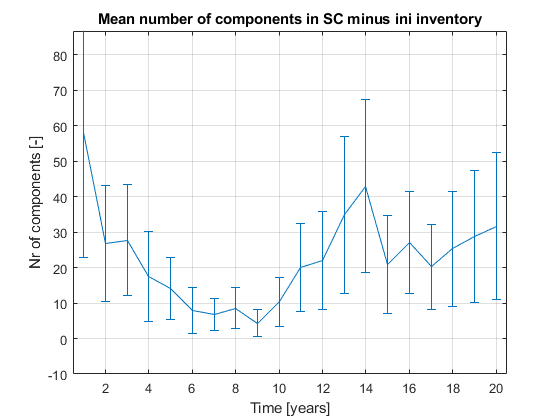

if true
    load('n_components_in_sc_index.mat')
    [r c] = size(n_components_in_sc_index)
    for i = 1:r
        for j = 1:c
            NOC = cell2mat(n_components_in_sc_index(i,j));
            mjNOC(j) = mean(NOC);
            vjNOC(j) = var(NOC);
        end
        mNOC(i) = mean(mjNOC);
        vNOC(i) = sqrt(sum(vjNOC)/c);
    end
    figure();
    errorbar([1:20],mNOC,vNOC);
    title('Mean number of components in SC minus ini inventory')
    xlabel('Time [years]')
    ylabel('Nr of components [-]')
    ylim([-10,50])
    xlim([0.5,20.5])
    grid on
end

Inventory

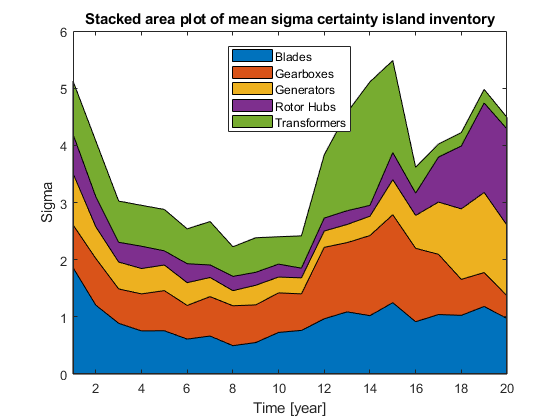

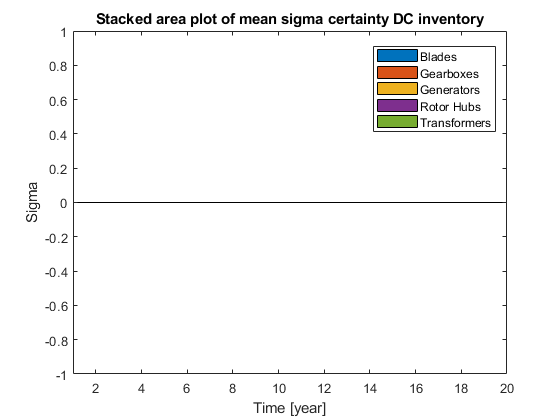

if true % Performance of inventory levels
    load('inventory_level_island_index.mat')
    load('inventory_level_distcenter.mat')
    [r c] = size(inventory_level_island_index);
    for i = 1:r
        for j = 1:c
        ILI = cell2mat(transpose(inventory_level_island_index(i,j)));
        inv_var_island(j,1:5) = var(ILI);
        
        ILDC = cell2mat(transpose(inventory_level_distcenter_index(i,j)));
        inv_var_distcenter(j,1:5) = var(ILDC);
        
        end
        inv_island_sigma(i,1:5) = sqrt(sum(inv_var_island)./3);
        inv_distcenter_sigma(i,1:5) = sqrt(sum(inv_var_distcenter)./3);
    end
    figure()
    area(inv_island_sigma)
    title('Stacked area plot of mean sigma certainty island inventory')
    xlabel('Time [year]')
    ylabel('Sigma')
    legend({'Blades','Gearboxes','Generators','Rotor Hubs','Transformers'},'Location','best')
    xlim([1 20])
    
    figure()
    area(inv_distcenter_sigma)
    title('Stacked area plot of mean sigma certainty DC inventory')
    xlabel('Time [year]')
    ylabel('Sigma')
    legend({'Blades','Gearboxes','Generators','Rotor Hubs','Transformers'},'Location','best')
    xlim([1 20])
end

## JIT Performance

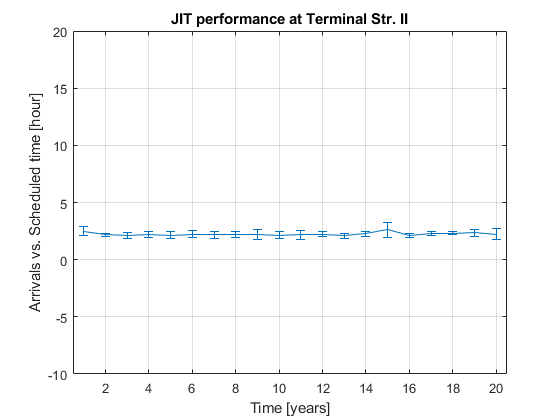

if true
    load('JIT_performance.mat')
    [r c] = size(JIT_performance);
    for i = 1:r
        for j = 1:(c/3)
            Arrivals = cell2mat(JIT_performance(i,3*j-2));
            Triggers = cell2mat(JIT_performance(i,3*j-1));
            Departures = cell2mat(JIT_performance(i,3*j));
            for h = 1:length(Arrivals)
                Arrivals_t = sum(Arrivals(h,:));
                Triggers_t = sum(Triggers(h,:));
                Departures_t = sum(Departures(h,:));
                if Arrivals_t >= Triggers_t
                    Perf(h,j) = Arrivals_t - Triggers_t;
                elseif Triggers_t > Departures_t
                    Perf(h,j) = Triggers_t - Departures_t;
                end
            end
        end
        Perf_t = sum(Perf) ./ sum(Perf~=0);
        Perf_m(i) = mean(Perf_t);
        Perf_s(i) = std(Perf_t);
    end
    figure();
    errorbar([1:20],Perf_m,Perf_s);
    title('JIT performance at Terminal Str. II')
    xlabel('Time [years]')
    ylabel('Arrivals vs. Scheduled time [hour]')
    ylim([-10,20])
    xlim([0.5,20.5])
    grid on
end